clear all
close all
clc
path = 'InvestmentReplica.mat';
load(path)
Date_ME = XTab.Date(:, :);

## 1. Data collection and objective

Construct a Monster Index to be replicated

% Synthetic target weights
wHFRXGL = 0.33; 
wMXWO = 0.33;
wLEGATRUU = 0.33;

% Building the target
y = wHFRXGL*price2ret(HFRXGL) + wMXWO*price2ret(MXWO) + wLEGATRUU*price2ret(LEGATRUU); % "Monster Index" returns
target = ret2price(y); % "Monster Index" levels

Check stationarity of the returns

CheckStationarity(y)

    The series is stationary


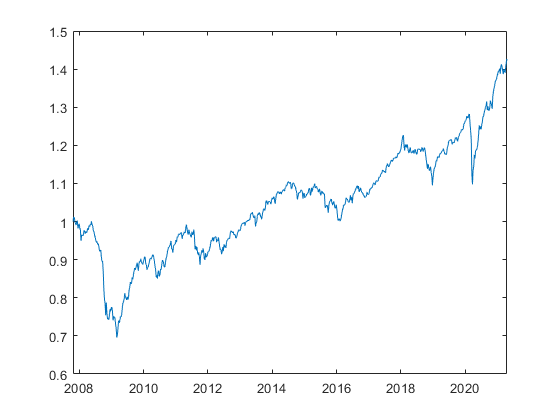

figure
plot(Date_ME,target)

Set of available future for replication

% Futures returns
Futures = [CO1 DU1 ES1 GC1 LLL1 NQ1 RX1 TP1 TU2 TY1 VG1];
X = price2ret(Futures);

for i = 1:size(X,2)
    display(['For the Future: ',num2str(i)])
    CheckStationarity(X(:,i))
end

For the Future: 1


    The series is stationary


For the Future: 2


    The series is stationary


For the Future: 3


    The series is stationary


For the Future: 4


    The series is stationary


For the Future: 5


    The series is stationary


For the Future: 6


    The series is stationary


For the Future: 7


    The series is stationary


For the Future: 8


    The series is stationary


For the Future: 9


    The series is stationary


For the Future: 10


    The series is stationary


For the Future: 11


    The series is stationary


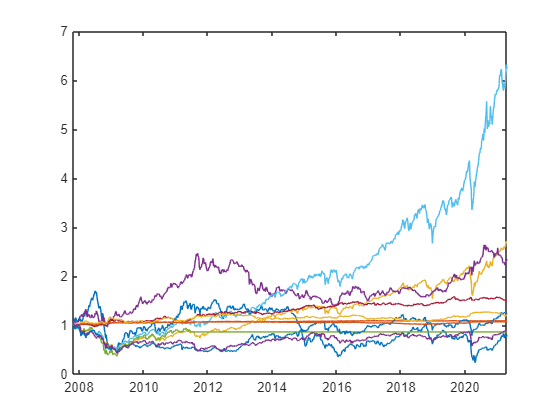

figure
plot(Date_ME,ret2price(X))

Define dimensionalities

% Load the return data
portfolioReturns = y;
futuresReturns = X;

n = size(portfolioReturns, 1);  % Number of time steps
m = size(futuresReturns, 2);    % Number of futures

## 2. Construction of a Regression benchmark

lasso e ridge 

coeff_lasso = LassoReg(X, y);

y_lasso = X*coeff_lasso;

% Tracking Error Volatility = (annualized) standard deviation of Tracking Error.
TEV_return = ComputeTEV(y_lasso,y)

TEV_return = 0.0288

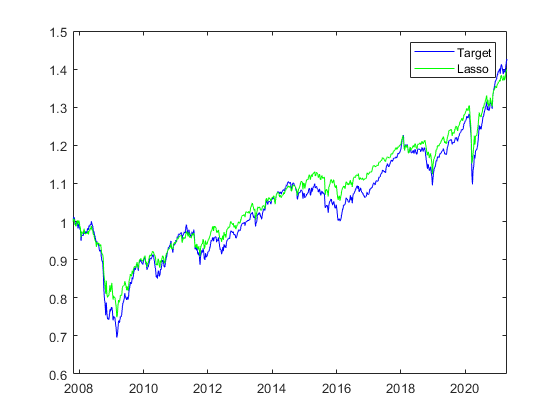

figure()
plot(Date,ret2price(y),'Color','b')
hold on
plot(Date,ret2price(y_lasso),'Color','g')
legend('Target','Lasso')

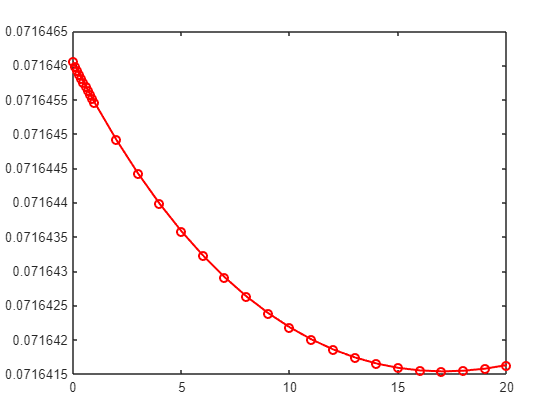

K = [(0:0.1:1)'; (2:20)'];
TEV_ridge = zeros(length(K),1);

for i = 1:length(K)
      coeff_ridge = ridge(y,X,K(i));
      y_ridge = X*coeff_ridge;
      TE_ridge = y - y_ridge;
      TEV_ridge(i) = std(TE_ridge)*sqrt(52);
end

figure
plot(K, TEV_ridge, '-or','LineWidth',1.5);

index = find(TEV_ridge == min(TEV_ridge));
min_k = K(index)

min_k = 17

## 3. Application of the Kalmann algorithm

Compute the weekly weights with Kalmann-Filter

% y = portfolioReturns; (already done above)
% F = eye(m) so it can be omitted
% G = zeros(m) so the associated term is removed
H = futuresReturns;
% D = 0 so the associated term is removed
V1 = eye(m).*std(futuresReturns); 
V2 = std(portfolioReturns); 
% V12 = 0 so the associated term is removed

model = InitializeModel(y, [], [], H, [], V1, V2, []);

### Different calibration attempts

####     1. Empirically determine an actual solutions for time t_0

TEV Kalman = 0.020639
TEV Benchmark = 0.028723


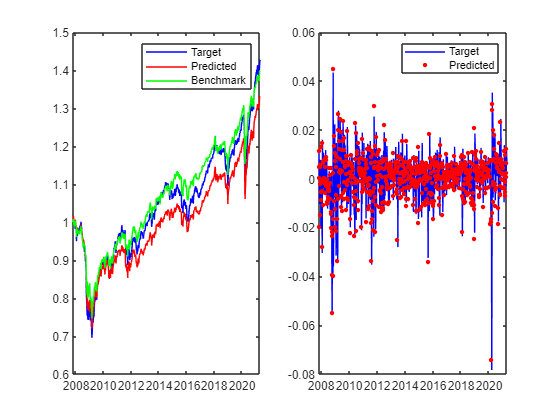

x_initial = ones(m,1)*0.065; % empirically obtained, intuitive best solution
[Weights,TEV_return] = mainKalman(model,x_initial,futuresReturns,Date_ME,y_lasso);

####     2. Try an almost random conbinations of wheights

TEV Kalman = 0.032792
TEV Benchmark = 0.028723


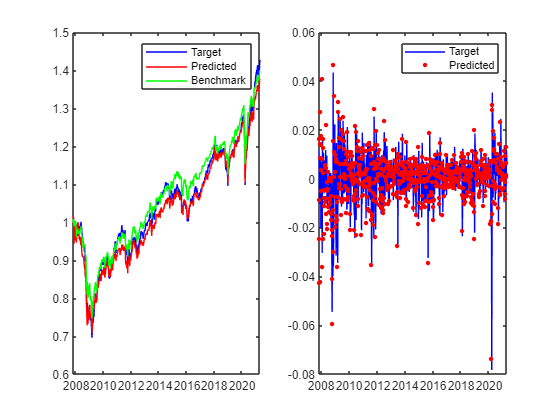

x_initial_temp = [-1/3 1/2 0 1/2 1/3 0 1/3 1/2 -1 1/2 -1/3]'; % to try with different initial values
[Weights_temp,TEV_return_temp] = mainKalman(model,x_initial_temp,futuresReturns,Date_ME,y_lasso);

####     3. Uniform whieghts

TEV Kalman = 0.021184
TEV Benchmark = 0.028723


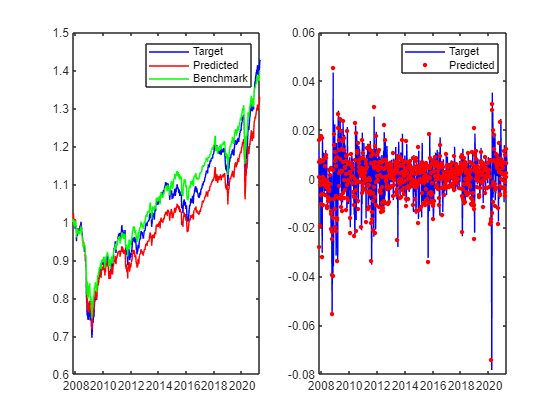

x_initial_temp = ones(m,1)/11; % to try with different initial values
[Weights_temp,TEV_return_temp] = mainKalman(model,x_initial_temp,futuresReturns,Date_ME,y_lasso);

### Statistical meausers

% Gross Total Return, and Excess Return (ER)
logRClone = diff(log(ret2price(Prediction))); 
logRTarget = diff(log(ret2price(y)));
logTE =  logRClone - logRTarget;
meanTRTarget = exp(mean(logRTarget)*52) - 1;
meanTRClone = exp(mean(logRClone)*52) - 1;
meanER = exp(mean(logTE)*52) - 1;
IR = meanER/TEV_return;

display(['IR = ',num2str(IR)])

IR = -0.17873


% R-squared
% Compute the residual sum of squares (RSS)
RSS = sum((y - Prediction).^2);
% Compute the total sum of squares (TSS)
TSS = sum((y - mean(y)).^2);
% Compute R-squared
R_squared = 1 - RSS / TSS;

display(['R^2 = ',num2str(R_squared)])

R^2 = 0.92068


## 4. Considerations on costs

### Weekly modifications

Actual cost of transaction (it is assumed to be 5$ for each transaction, indipendently of how the quantity selled or buyed but just of the open transaction to change a wheight)

CostTransaction = 5;

Price for weekly change (if asked to do) the wheigts

Cost_weekly = ComputeCost(Weights,CostTransaction)

ans =    688   250   671   669   259   676   632   672   306   630   674


Cost_weekly = 30635

### Monthly modifications

Wheights constant in the month as at it beginning

Weights_monthly = Weights;
for i = 2:n
    if Date_ME(i).Month == Date_ME(i-1).Month
        Weights_monthly(:,i) = Weights(:,i-1);
    else
        Weights_monthly(:,i) = Weights(:,i);
    end
end

Prediction_1 = sum(futuresReturns.*Weights_monthly',2);
TEV_return = ComputeTEV(Prediction_1,y)

TEV_return = 0.0300

Cost_monthly = ComputeCost(Weights_monthly,CostTransaction)

Cost_monthly = 24085

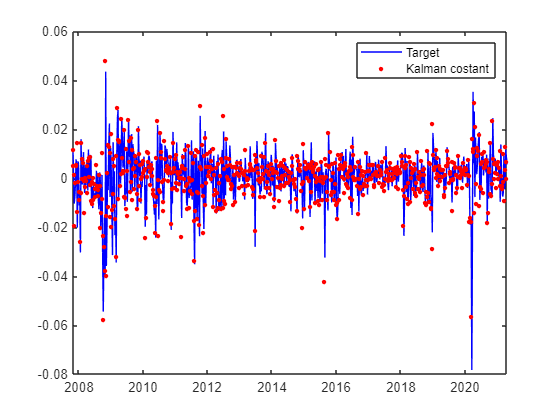

figure()
plot(Date_ME(2:end),y,'Color','b')
hold on
plot(Date_ME(2:end),sum(futuresReturns.*Weights_monthly',2),'r.','MarkerSize',10)
legend('Target','Kalman costant')

### Constant wheights

Find optimal wheights based on Tev

min_TEV = 9999;
for i = 1:n
    TE = sum(futuresReturns*Weights(:,i),2) - y;
    TEV = std(TE)*sqrt(52);
    if TEV < min_TEV
        min_TEV = TEV;
        Weights_constant = Weights(:,i);
    end
end

Prediction_1 = sum(futuresReturns*Weights_constant,2);
TEV_return = ComputeTEV(Prediction_1,y)

TEV_return = 0.0297

Cost_yearly = ComputeCost(Weights_constant,CostTransaction)

Cost_yearly = 55

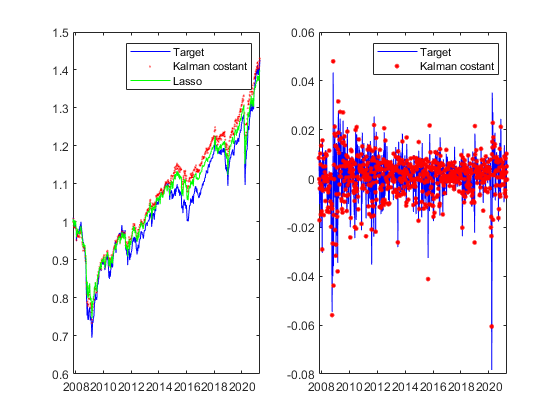

figure()
subplot(1,2,1)
plot(Date_ME,target,'Color','b')
hold on
plot(Date_ME,ret2price(Prediction_1),'r.','MarkerSize',1)
plot(Date,ret2price(y_lasso),'Color','g')
legend('Target','Kalman costant','Lasso')

subplot(1,2,2)
plot(Date_ME(2:end),y,'Color','b')
hold on
plot(Date_ME(2:end),Prediction_1,'r.','MarkerSize',10)
legend('Target','Kalman costant')

## 5. Conclusions

So, what do we conclude?

From a theoretical point of view the idea of dynamical wheights given by an algorithm as the Kalman filter is quite interesting,

However the application to reality is not so meaningfull. Indeed, first of all the new approach is quite sensitive to the initial parameters and this can induce in high unpredictability on the result reducing the capability of the model to be standardized and resused in different context. Moreover, dynamical wheights, that in theory seems to be an excellent solution, requires an associated cost of transaction, each time they are modified, inducing in really high costs.

On this last term is important to observe that, even when we decid to let the weight constant for the month or in general, starting from an analysis of the Kalman algorithm week result, and so reducing the cost of transaction at same level of the one given by the Regression approach, at each week if we wonna retest our model for validation we have to be really carefull on the calibration.

Our conclusion is then that, even if a regression model approach can be less precise (assuming to find a suffciently good calibration for the Kalmann filter) it is more robust and cost effective.